# C&PE 778 Homework 01                                 William Powers 2025

#### ***1. Characterize the extrema of the following function:***

#### 
$$f(\mathbf{x})=2x_1^3+x_2^2+4x_1x_2+3$$


Finding the functions extrema involves identifying its critical points, where the derivative is equal to zero, and classifying each as either a maximum, minimum, or saddle point. The derivative of $f(\mathbf{x})$ with respect to $x_1$ and $x_2$ are


$$f(\mathbf{x})\prime_{x_1} = 6x_1^2+4x_2$$
     
$$f(\mathbf{x})\prime_{x_2} = 2x_2+4x_1$$


Setting these equal to zero and solving gives a system of equations specifying the critical points of intereset


$$0=6x_1^2+4x_2$$
    
$$0=2x_2 + 4x_1$$


s$x_1 = [0, 4/3]$    $x_2=[0, -8/3]$


$$\text{CP's}=(0,0), \ (0,-8/3), \ (4/3,0), \ (4/3, -8/3)$$


Given these four critical points, the next step in categorizing these extrema is calculating the Hessian matrix.


$$f(\mathbf{x})\prime\prime_{x_1 x_1} = 12x_1$$
    
$$f(\mathbf{x})\prime\prime_{x_1 x_2} = 4
$$
    
$$f(\mathbf{x})\prime\prime_{x_2 x_2} = 2$$
    
$$f(\mathbf{x})\prime\prime_{x_2 x_1} = 4$$



$$H(f) = \left[
\begin{array}{cc}
12x_1 & 4 \\
4 & 2
\end{array}
\right]



$$


The definiteness of the Hessian determines the convexity of the function. To determine whether the Hessian is positive or negative definite, the eigenvalues are calculated from the characteristic equation $\text{det} \left( \lambda I - H \right) = 0$.


$$\text{det} \left(  

\left[
\begin{array}{cc}
\lambda \\
\lambda
\end{array}
\right]

\left[
\begin{array}{cc}
1 & 0 \\
0 & 1
\end{array}
\right]

-

\left[
\begin{array}{cc}
12x_1 & 4 \\
4 & 2
\end{array}
\right]

\right) = 0$$


From here, the eigenvalues are classified using the following table:

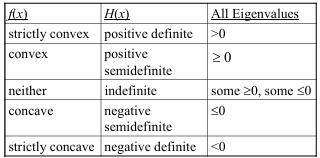

Because the eigen-analysis of this problem may be difficult (stemming from the dependence on $x_1$), we can instead apply the second derivative test at each point. The test states the following

**If **$\text{det}\left( H(x_1, x_2) \right) > 0$** and **$f(x_1, x_2)^{''}_{x_1 x_1} > 0$** then **$0 \rightarrow$** local minimum.**

**If **$\text{det}\left( H(x_1, x_2) \right) > 0$** and **$f(x_1, x_2)^{''}_{x_1 x_1} < 0$** then **$0 \rightarrow$** local minimum.**

**If **$\text{det}\left( H(x_1, x_2) \right) < 0$$\rightarrow$** saddle point.**

**If **$\text{det}\left( H(x_1, x_2) \right) = 0$ $\rightarrow$**inconclusive.**

Using this test each point can be checked

$\text{det}(H(0, 0)) = 24(0)-16 < 0 \rightarrow$ saddle point.

$\text{det}(H(0, -8/3)) = 24(0)-16 < 0 \rightarrow$ saddle point.

$\text{det}(H(4/3, 0)) = 24(4/3)-16 > 0$ and $f(4/3, 0)^{''}_{x_1 x_1} = 12(4/3) > 0 \rightarrow$ local minimum.

$\text{det}(H(4/3, -8/3)) = 24(4/3)-16 > 0$ and $f(4/3, -8/3)^{''}_{x_1 x_1} = 12(4/3) > 0 \rightarrow$ local minimum.

For multivariate cases, we can also use the following relationship, derived from a multivariate Taylor series expansion of $F(\mathbf{x})$ to check for convexity

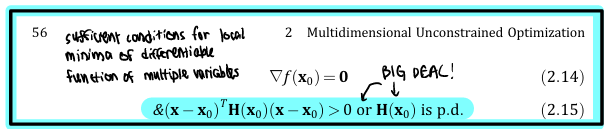

#### 2. Determine the convexity of $f(\mathbf{x})=e^{x_1} + e^^{x_2}$ using the Hessian matrix.

Similarly to (1), the hessian is determined by the second partial derivatives with respect to each variable. First, the critical points of $f(x_1, x_2)$, are found


$$f(x_1, x_2)_{x_1}^{'} = x_1 e^{x_1}$$
    
$$f(x_1, x_2)_{x_2}^{'} = x_2 e^{x_2}$$



$$\text{CP} = (0, 0)$$


Next, the second derivatives taken, and the Hessian plus its determinate are constructed.


$$f(x_1, x_2)_{x_1 x_1}^{''} = x_1^2 e^{x_1}$$
    
$$f(x_1, x_2)_{x_2 x_2}^{''} = x_2^2 e^{x_2}$$
    
$$f(x_1, x_2)_{x_1 x_2}^{''} = 0$$
   
$$f(x_1, x_2)_{x_2 x_1}^{''} = 0$$



$$H(f) = \left[
\begin{array}{cc}
x_1^2e^{x_1} & 0 \\
0 & x_2^2e^{x_2}
\end{array}
\right]



$$
    
$$\text{det}(H) = x_1^2 x_2^2 e^{x_1 + x_2}$$


Using the second derivative test from above

$\text{det}(H(0, 0)) = 0 \rightarrow$inconclusive.

Becuase this method was unsucessful, the Hessian definiteness test is used instead.


$$\text{det} \left(  

\left[
\begin{array}{cc}
\lambda \\
\lambda
\end{array}
\right]

\left[
\begin{array}{cc}
1 & 0 \\
0 & 1
\end{array}
\right]

-

\left[
\begin{array}{cc}
x_1^2e^{x_1} & 0 \\
0 & x_2^2e^{x_2}
\end{array}
\right]

\right) = 0$$
    
$$\lambda_1 = x_1^2 e^{x_1}$$
    
$$\lambda_2 = x_2^2 e^{x_2}$$


From this result, we can see that the Hessian will be positive semi-definite, and therefore convex whenever $x_1$ and $x_2$ are restricted to be greater than or equal to zero. Thus to make the problem convex, the feasible solution region must be constrained to $x_1 \ge 0$ nd $x_2 \ge 0$.

#### 3. Write a MATLAB program to solve the following linear programming problem:


$$\text{max} \ z=8x_1+9x_2+5x_3$$



$$\text{s.t.} \\ 
x_1 + x_2 + x_3 \le 2 \\
2x_1 +3 x_2 + 4x_3 \le 3 \\
6x_1 + 6x_2 + 2x_3 \le 8 \\
x_1 \ge 0 \ x_2 \ge 0 \ x_3 \ge 0

$$


% Decision variable: x = [x1; x2; x3]
% Objective: minimize J(x) = 8*x1 + 9*x2 + 5*x3
% Constraints:
%   x1 + x2 + x3          <= 2
%   2*x1 + 3*x2 + 4*x3    <= 3
%   6*x1 + 6*x2 + 2*x3    <= 8
%   x >= 0

% --- Objective (with gradient) ---
obj = @(x) deal(8*x(1) + 9*x(2) + 5*x(3), [8; 9; 5]);  % f, grad f

% --- Linear inequalities A*x <= b ---
A = [1 1 1;
     2 3 4;
     6 6 2];
b = [2; 3; 8];

% --- Bounds ---
lb = [0; 0; 0];
ub = [];  % no explicit upper bounds

% --- fmincon options ---
opts = optimoptions('fmincon', ...
    'Algorithm','interior-point', ...
    'Display','iter', ...
    'SpecifyObjectiveGradient', true);

% --- Initial guess ---
x0 = [0.1; 0.1; 0.1];

% --- Solve ---
[x_opt, f_opt, exitflag, output, lambda] = fmincon(obj, x0, A, b, [], [], lb, ub, [], opts);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.200000e+00    0.000e+00    6.837e-01
    1       2    2.215890e-02    0.000e+00    4.670e-01    1.716e-01
    2       3    2.184504e-03    0.000e+00    6.949e-04    1.627e-03
    3       4    3.064598e-05    0.000e+00    8.945e-05    2.058e-04
    4       5    2.999342e-07    0.000e+00    1.772e-07    2.658e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the 


disp('Optimal x:'), disp(x_opt)

Optimal x:
   1.0e-07 *

    0.1251
    0.1112
    0.1997



disp('Optimal objective J:'), disp(f_opt)

Optimal objective J:
   2.9993e-07



disp('Exitflag:'), disp(exitflag)

Exitflag:
     1

